# Final Lab Exam (10 / 06 / 2021)

### EXERCISE 1

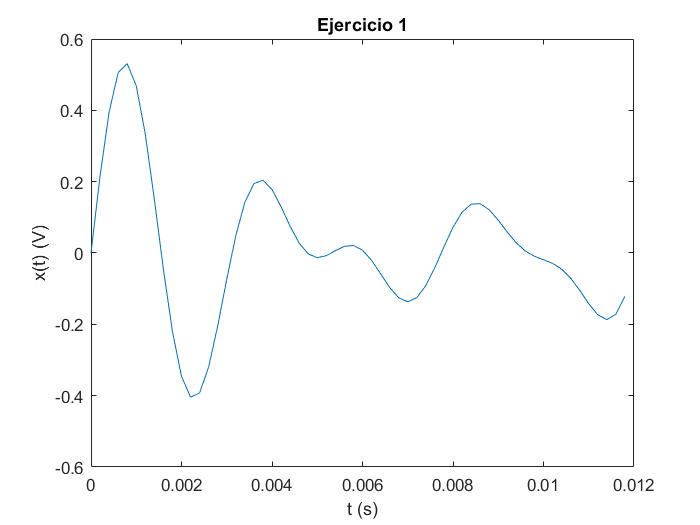

[x, fs] = audioread('audio\septima.wav');

N = 0.012 * fs;     % Number of samples.
n = 0 : N - 1;      % Discrete time vector for the fragment.

% Plot the first 15 ms in the time domain.
t = n / fs;
plot(t, x(1 : N));
title('Exercise 1');
xlabel('t (s)'), ylabel('x(t) (V)');

### EXERCISE 2

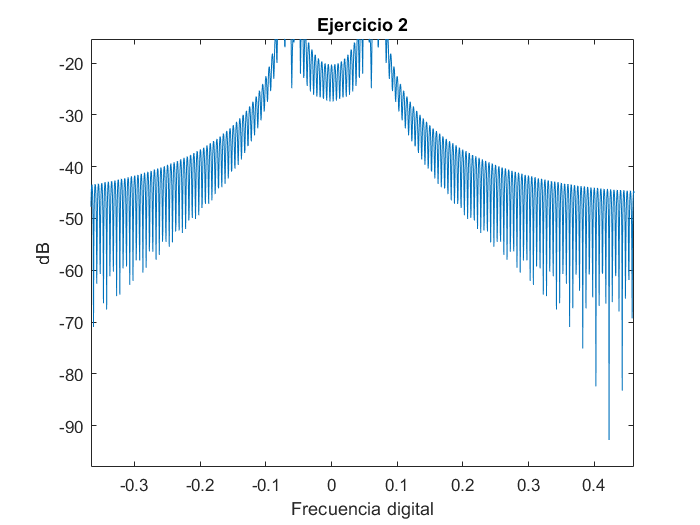

L = 200;
N = 2048; % Smallest power of 2 that meets the criteria.
rect = 1 : L;
x_rect = x(1 : L);

% Compute the spectrum.
spectrum = fft(x_rect, N);                      % Compute FFT.
spectrumShifted = fftshift(spectrum);           % Shift spectrum to the origin.

% Plot spectrum magnitude (logarithmic).
f = (0 : (N - 1)) / N - 0.5;
plot(f, 20 * log10(abs(spectrumShifted) / max(abs(spectrumShifted))));
title('Exercise 2');
ylabel('dB'), xlabel('Digital frequency');

### EXERCISE 3

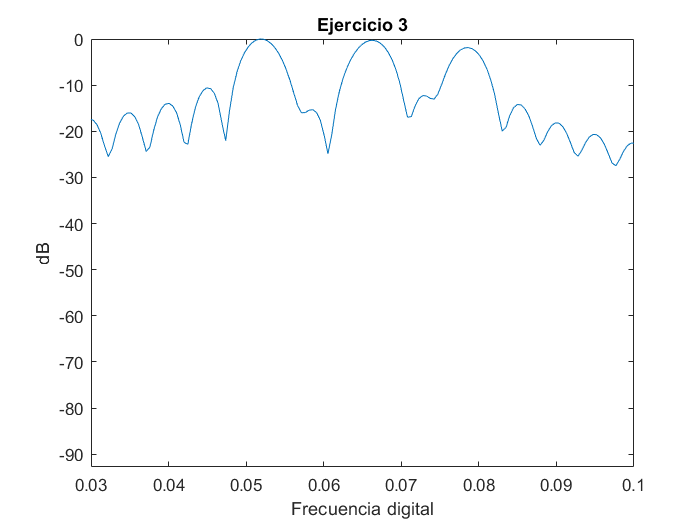

plot(f, 20 * log10(abs(spectrumShifted) / max(abs(spectrumShifted))));
axis([0.03 0.1 -inf inf]);
title('Exercise 3');
ylabel('dB'), xlabel('Digital frequency');